# Measuring SpO₂ and Pulse Rate Lab

## Introduction

Pulse oximetry is a non-invasive optical technique used to measure the oxygen saturation level (SpO₂) of arterial blood and monitor pulse rate. It plays a critical role in assessing a patient's respiratory and cardiovascular health, both in clinical settings and for personal health monitoring. The method relies on **photoplethysmography (PPG)**, which involves detecting blood volume changes in the microvascular bed of tissue using light absorption characteristics.

In pulse oximetry, a sensor emits **red and infrared (IR) light** through a body part, typically a fingertip or earlobe. The sensor measures the amount of light absorbed by the blood, which varies with the pulsatile changes in arterial blood volume associated with each heartbeat. **Oxyhemoglobin** and **deoxyhemoglobin** absorb light differently at red and IR wavelengths, allowing for the estimation of SpO₂ based on the ratio of absorbed red and IR light.

The PPG signal obtained from the sensor consists of two components:

- **AC Component**: The pulsatile part of the signal caused by the arterial blood volume changes with each heartbeat. This component is used to determine the **pulse rate**, as the peaks correspond to individual heartbeats.

- **DC Component**: The non-pulsatile part due to the constant absorption by tissues, venous blood, and non-pulsatile arterial blood.

By analyzing the AC component of the PPG signal, we can extract the pulse rate by detecting the time intervals between successive peaks. The ratio of the AC to DC components at both red and IR wavelengths is used to calculate SpO₂ using the **ratio-of-ratios method**.

In this lab, you will work with red and IR waveform data collected using a finger clip sensor connected to an Arduino device. You will apply signal processing techniques to extract meaningful physiological parameters, specifically SpO₂ and pulse rate, from the PPG signals. Through this process, you will gain insights into the principles of photoplethysmography and pulse oximetry, understand how pulse rate is measured from PPG signals, and appreciate the importance of robust algorithms in the presence of motion artifacts and physiological variations.

**Note:** You should perform the initial analysis and code development using the clean signal, and then apply the same analysis on the signals with intentionally induced motion artifacts to observe the effects of noise on physiological signal processing.

**Learning Objectives:**

- Understand the principles of pulse oximetry and its clinical significance

- Import and preprocess red and IR signals obtained from a finger clip sensor

- Apply filtering techniques to remove noise and artifacts from the signal

- Separate the AC and DC components of the signals and understand their physiological relevance

- Implement peak detection algorithms to extract pulse rate from the IR signal

- Compute SpO₂ levels using the ratio-of-ratios method and sensor calibration polynomial

- Analyze the impact of motion artifacts and respiration rates on SpO₂ and pulse rate measurements

- Compare computed values with reference measurements and discuss discrepancies

## Signal Acquisitions

**Equipment:**

- Arduino software and CoolTerm installed on your laptop

- Arduino device with measurement shield and finger clip sensor

- Reference pulse oximeter (e.g., Beurer PO40)

- Stopwatch or timer

**Measurements:**

Perform the following measurements, each lasting **30 seconds**:

- **Period 1:** Baseline measurement with no finger motion

- **Period 2:** Measurement with mild finger motion

- **Period 3:** Measurement with severe finger motion

- **Period 4:** Repeat of Period 1 to verify reproducibility

- **Period 5:** Measurement with no finger motion but varying respiration rates (10, 15, and 20 breaths per minute)

**Instructions for Each Measurement:**

- Start recording data with CoolTerm

- Perform the specified condition for the period (e.g., remain still, introduce motion)

- Record pulse rate and SpO₂ from the reference device

- Stop recording after 30 seconds

- Save data and note any observations (e.g., motion artifacts, comfort level)

*During Period 5, guide the test subject to maintain respiration rates of 10, 15, and 20 breaths per minute.*

**Write down your reference measurements below:**

%% Student 1
% P1_PR = ;   %Pulse Rate from arduino device
% P1_SpO2 = ; % SpO2 from arduino device
% P2_PR = ;   
% P2_SpO2 = ;
% P3_PR = ;   
% P3_SpO2 = ;
% P4_PR = ;   
% P4_SpO2 = ;
% P5_PR = ;   
% P5_SpO2 = ;

%% Student 2
% P1_PR = ;   %Pulse Rate from arduino device
% P1_SpO2 = ; % SpO2 from arduino device
% P2_PR = ;   
% P2_SpO2 = ;
% P3_PR = ;   
% P3_SpO2 = ;
% P4_PR = ;   
% P4_SpO2 = ;
% P5_PR = ;   
% P5_SpO2 = ;


%% Student 3
% P1_PR = ;   %Pulse Rate from arduino device
% P1_SpO2 = ; % SpO2 from arduino device
% P2_PR = ;   
% P2_SpO2 = ;
% P3_PR = ;   
% P3_SpO2 = ;
% P4_PR = ;   
% P4_SpO2 = ;
% P5_PR = ;   
% P5_SpO2 = ;

## Data Analysis

### Step 0: Run MATLAB Commands for Clearing and Resetting

Before you begin, it is essential to clear all existing variables, close any open figures, and reset the command window to avoid conflicts and ensure a clean workspace.

close all;
clear;
clc;

### Step 1: Load and Inspect the Data

We will load the SpO₂ data, which contains time-series measurements of red and infrared (IR) signals obtained from the finger clip sensor. These signals are used to compute the oxygen saturation level in the blood and monitor pulse rate.

**Exercise 1:** Modify the `folder_path` and `data_file` variables to match the location of your SpO₂ data files.

**Instructions:**

- Set the correct folder path where your data files are stored

- Specify the correct data file name

- Use the `readtable` function to load the data into MATLAB

- Display the column names and preview the first few rows to ensure the data is correctly imported

% Specify the folder path and file name
folder_path = 'C:\Users\20181588\Desktop\TA Monitoring Resp & Circ\Measuring SpO2 and Pulse Rate';  % <-- Modify this path
data_file = 'SpO2_data_Anton_v1.xlsx';    % <-- Modify this file name

% Read the data from the CSV file
data = readtable(fullfile(folder_path, data_file), 'VariableNamingRule', 'preserve');

% Display column names
disp(data.Properties.VariableNames);

    {'t [s]'}    {'Red [bit]'}    {'IR [bit]'}



% Display the first few rows of data
disp('First few rows of the imported data:');

First few rows of the imported data:


head(data);

    t [s]    Red [bit]    IR [bit]
    _____    _________    ________

        0      50757       55256  
    0.008      50756       55254  
    0.016      50755       55252  
    0.024      50754       55251  
    0.032      50753       55251  
     0.04      50755       55253  
    0.048      50757       55256  
    0.056      50761       55262  



% Extract time and signal data
time = data.('t [s]');           % Adjust column name if different
red_signal = data.('Red [bit]');      % Adjust column name if different
ir_signal = data.('IR [bit]');        % Adjust column name if different


### Step 2: Signal Preprocessing

The signals obtained from the sensor may contain noise and artifacts due to various factors such as ambient light interference, motion artifacts, and electronic noise. Preprocessing the signals is essential to enhance signal quality and extract meaningful physiological information.

Photoplethysmography (PPG) signals have specific characteristics:

- **Frequency Content:** The fundamental frequency corresponds to the heart rate, typically between 0.8 Hz to 2 Hz (48 bpm to 120 bpm) for adults

- **Noise Sources:** Include motion artifacts, ambient light, and high-frequency electronic noise

To isolate the useful information, we need to apply filtering techniques.

**Exercise 2:** Apply a band-pass filter to both red and IR signals to remove unwanted noise and artifacts.

**Instructions:**

- Decide on appropriate cutoff frequencies for the band-pass filter based on the expected heart rate range

- Design a Butterworth band-pass filter using the `butter` function

- Apply the filter to the red and IR signals using the `filtfilt` function to avoid phase distortion

% Define the sampling frequency
fs = 125;  % Sampling rate in Hz (as specified by the Arduino device)

% Design a Band-Pass Filter for PPG signals
% Expected heart rate range: 0.8 Hz to 2 Hz (approximate)
% We'll extend the range slightly to account for variability

% --- Your code here ---
% Define filter parameters
f_pass_low = 0;  % Lower cutoff frequency (Hz)
f_pass_high = 0;   % Upper cutoff frequency (Hz)
filter_order = 0;  % Order of the Butterworth filter

% Normalize the cutoff frequencies
Wn = 0 ;

% Design the Butterworth band-pass filter
[b_bp, a_bp] = 0;

% Apply the filter to the red and IR signals
filtered_red = 0;
filtered_ir = 0;


**Reflective Questions:**

- **Filter Design:** Why is a band-pass filter suitable for PPG signals?

- **Cutoff Frequencies:** How do the chosen cutoff frequencies relate to the physiological heart rate range?

- **Filter Order:** How does the filter order affect the steepness of the filter's response?

### **Step 3: **Plotting the Raw and Filtered Signals

Visualizing the signals before and after filtering helps us understand the effect of the preprocessing step.

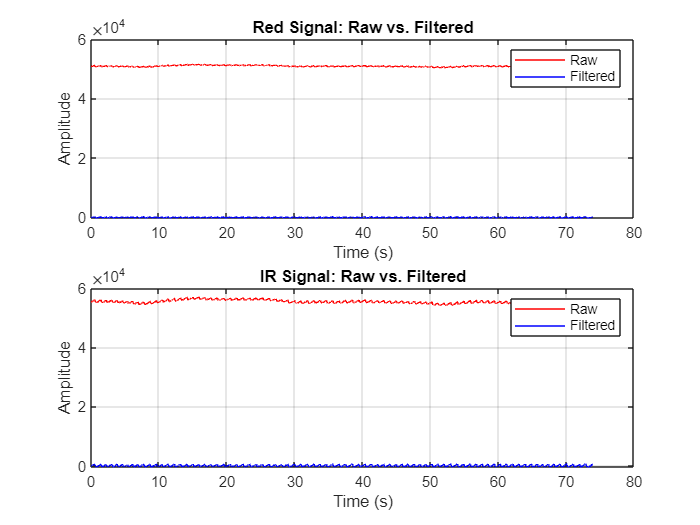

% Plot the raw and filtered signals
figure('Name', 'Raw vs. Filtered Signals');

subplot(2,1,1);
plot(time, red_signal, 'r'); hold on;
plot(time, filtered_red, 'b');
title('Red Signal: Raw vs. Filtered');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Raw', 'Filtered');
grid on;

subplot(2,1,2);
plot(time, ir_signal, 'r'); hold on;
plot(time, filtered_ir, 'b');
title('IR Signal: Raw vs. Filtered');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Raw', 'Filtered');
grid on;

**Expected Observations:**

- **Signal Improvement:** The filtered signals should have reduced noise compared to the raw signals

- **Noise Reduction:** Unwanted high-frequency noise and baseline wander should be attenuated

- **Preservation of Information:** The pulsatile nature of the PPG signal should be preserved in the filtered signals

**Reflective Questions:**

- **Signal Improvement:** How did filtering affect the appearance of the signals?

- **Noise Reduction:** Did the filtering process remove unwanted noise components?

- **Preservation of Information:** Is the pulsatile nature of the PPG signal preserved after filtering?

### **Step 4: Separating AC and DC Components**

The PPG signal consists of an AC component and a DC component:

- **AC Component:** Represents the pulsatile changes due to arterial blood volume changes with each heartbeat

- **DC Component:** Represents the non-pulsatile part due to constant absorption from tissues and non-pulsatile blood

Isolating the AC and DC components is crucial for calculating the SpO₂ level and pulse rate.

**Exercise 3:** Separate the AC and DC components from the filtered red and IR signals.

**Instructions:**

- Use a low-pass filter to extract the DC component from the **raw signals**.

- Subtract the DC component from the raw signals to obtain the AC component.

% --- Your code here ---
% Design a Low-Pass Filter for DC component extraction
dc_cutoff_freq = 0;  % Cutoff frequency for DC component (Hz)
Wn_dc = dc_cutoff_freq / (fs / 2);
[b_dc, a_dc] = 0;

% Extract DC components from raw signals
dc_red = 0;
dc_ir = 0;
% Extract AC components
ac_red =  0;
ac_ir = 0;


**Reflective Questions:**

- **Physiological Meaning:** What does the DC component represent in terms of tissue and blood absorption?

- **Importance of AC Component:** Why is the AC component critical for pulse rate and SpO₂ calculations?

- **Effectiveness of Separation:** How effective was the filtering in isolating the AC and DC components?

### **Step 5: Plotting the AC and DC Components**

Visualizing the AC and DC components helps us understand their contributions to the overall signal.

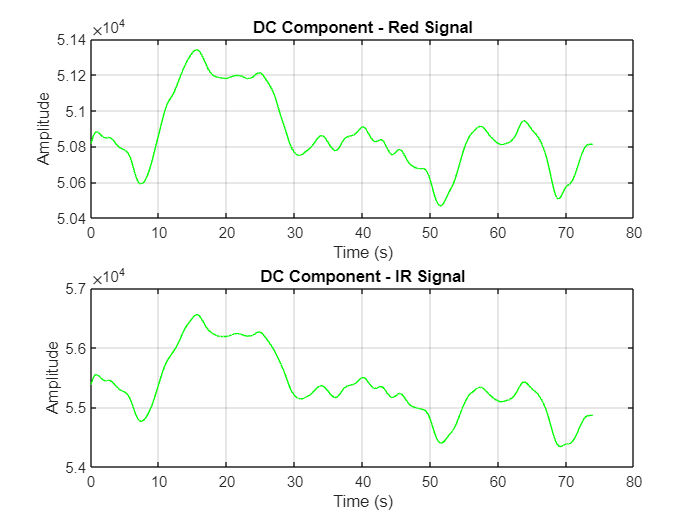

% Plot the DC components
figure('Name', 'DC Components');

subplot(2,1,1);
plot(time, dc_red, 'g');
title('DC Component - Red Signal');
xlabel('Time (s)'); ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(time, dc_ir, 'g');
title('DC Component - IR Signal');
xlabel('Time (s)'); ylabel('Amplitude');
grid on;

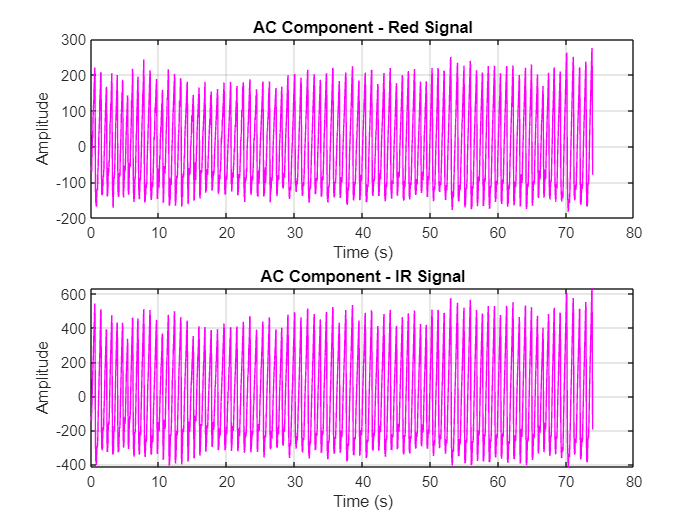


% Plot the AC components
figure('Name', 'AC Components');

subplot(2,1,1);
plot(time, ac_red, 'm');
title('AC Component - Red Signal');
xlabel('Time (s)'); ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(time, ac_ir, 'm');
title('AC Component - IR Signal');
xlabel('Time (s)'); ylabel('Amplitude');
grid on;

**Expected Observations:**

- **DC Components:** Should appear as steady signals representing baseline absorption

- **AC Components:** Should show pulsatile patterns corresponding to heartbeats

**Reflective Questions:**

- **Component Analysis:** Do the AC components show clear pulsatile patterns corresponding to heartbeats?

- **Signal Proportions:** How does the amplitude of the AC component compare to the DC component?

- **Potential Issues:** Are there any distortions or anomalies in the separated components?

### **Step 6: Peak Detection for Pulse Rate Extraction**

Pulse rate can be extracted by detecting peaks in the AC component of the IR signal. Accurate peak detection is essential for reliable pulse rate calculation.

**Exercise 4:** Implement a peak detection algorithm to identify individual heartbeats in the AC component of the IR signal.

**Instructions:**

- Use the `findpeaks` function to detect peaks in the **filtered IR signal**

- Choose appropriate values for `MinPeakHeight` and `MinPeakDistance` based on physiological heart rate limits

- Convert peak locations to sample indices for further calculations

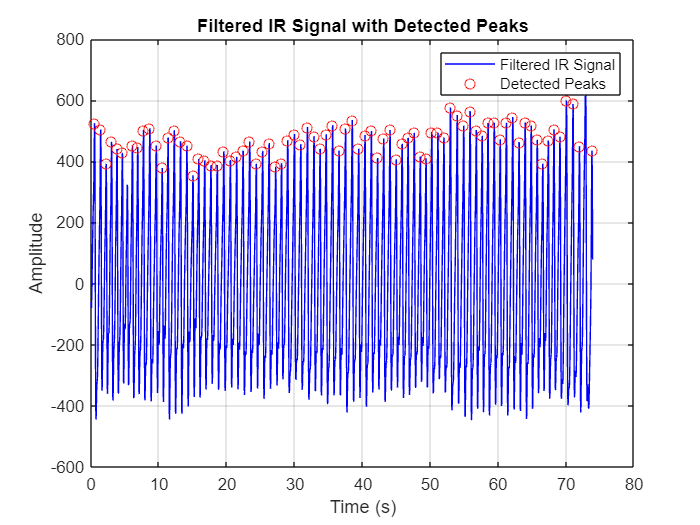

% --- Your code here ---
% Set parameters for peak detection
min_peak_height = 0;  % Threshold based on signal amplitude
min_peak_distance = 0;  % Minimum samples between peaks (assuming minimum heart rate of 60 bpm)

% Detect peaks in the filtered IR signal
[peaks_ir, locs_ir_samples] = findpeaks();

% Convert sample indices to time
locs_ir = 0;

% Plot the filtered IR signal with detected peaks
figure('Name', 'Peak Detection on Filtered IR Signal');
plot(time, filtered_ir, 'b'); hold on;
plot(locs_ir, peaks_ir, 'ro');
title('Filtered IR Signal with Detected Peaks');
xlabel('Time (s)'); ylabel('Amplitude');
legend('Filtered IR Signal', 'Detected Peaks');
grid on;

**Expected Observations:**

- The detected peaks should correspond to individual heartbeats

- Peaks should be evenly spaced if the heart rate is steady

**Reflective Questions:**

- **Parameter Selection:** How did you determine appropriate values for `MinPeakHeight` and `MinPeakDistance`?

- **Detection Accuracy:** Are all heartbeats correctly detected, or are there missed or false detections?

- **Signal Quality Impact:** How does the quality of the AC signal affect peak detection?

### **Step 7: Calculating Pulse Rate**

By measuring the time intervals between successive heartbeats (peak-to-peak intervals), we can calculate the pulse rate.

**Exercise 5:** Calculate the pulse rate in beats per minute (bpm) using the detected peaks.

**Instructions:**

- Calculate the time differences between successive peaks (inter-beat intervals)

- Convert these intervals to pulse rate in bpm

- Plot the pulse rate over time to observe any variations

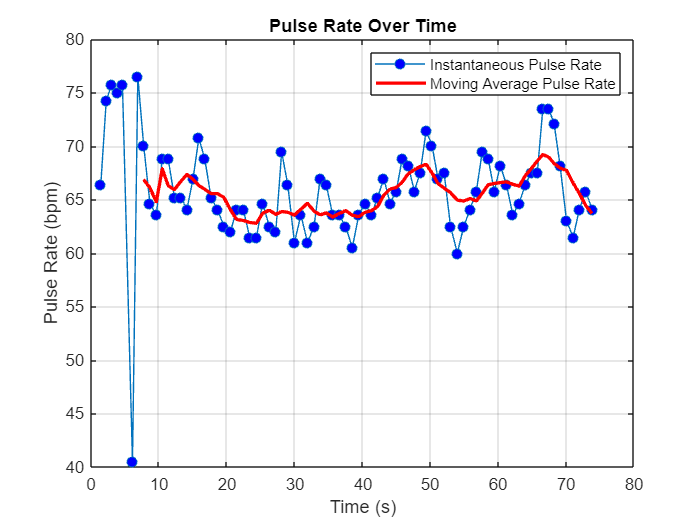

% --- Your code here ---
% Calculate inter-beat intervals
ibi = 0;  % Time intervals between peaks in seconds

% Calculate instantaneous pulse rate
pulse_rate_instant = 0 ;  % Convert intervals to bpm

% Calculate moving average over 8 beats to smooth the pulse rate
window_size = 8;
pulse_rate_moving_avg = movmean();

% Plot pulse rate over time
figure('Name', 'Pulse Rate Over Time');
plot(locs_ir(2:end), pulse_rate_instant, '-o', 'MarkerFaceColor', 'b');
hold on;
plot(locs_ir(window_size+1:end), pulse_rate_moving_avg(window_size:end), '-r', 'LineWidth', 2);
title('Pulse Rate Over Time');
xlabel('Time (s)'); ylabel('Pulse Rate (bpm)');
legend('Instantaneous Pulse Rate', 'Moving Average Pulse Rate');
grid on;

**Expected Observations:**

- **Variability:** There may be slight variations in the instantaneous pulse rate

- **Smoothing Effect:** The moving average should provide a smoother representation of the pulse rate

**Reflective Questions:**

- **Variability:** What factors might contribute to variations in the instantaneous pulse rate?

- **Moving Average Effect:** How does applying a moving average affect the pulse rate data?

- **Comparison with Reference:** How does the calculated pulse rate compare with the reference measurements?

### **Step 8: Computing SpO₂ Levels per Beat**

SpO₂ is calculated using the ratio-of-ratios method, which compares the AC and DC components of the red and IR signals. This method is based on the different absorption properties of oxyhemoglobin and deoxyhemoglobin at red and IR wavelengths.

**Exercise 6:**  Compute the SpO₂ percentage **per beat** using the ratio-of-ratios method and the sensor's calibration polynomial.

**Instructions:**

- For each beat (interval between successive peaks), compute the AC amplitude (peak-to-peak) of the AC components

- Compute the mean values of the DC components within each beat

- Calculate the ratio $R= \frac{(AC_{\text{red}} / DC_{\text{red}})}{(AC_{\text{IR}} / DC_{\text{IR}})}$ per beat

- Apply the calibration polynomial to convert RRR into SpO₂ percentage per beat

- Use appropriate calibration constants provided by the sensor manufacturer

% --- Your code here ---
% Calibration constants provided by the sensor manufacturer
A = -2.8668;
B = -23.155;
C = 110.27;

% Initialize variables
num_beats = length(locs_ir_samples) - 1;
AC_red_per_beat = zeros(num_beats,1);
DC_red_per_beat = zeros(num_beats,1);
AC_ir_per_beat = zeros(num_beats,1);
DC_ir_per_beat = zeros(num_beats,1);
R_per_beat = zeros(num_beats,1);
SpO2_per_beat = zeros(num_beats,1);
beat_times = zeros(num_beats,1);

for i = 1:num_beats
    % Indices for current beat
    idx_start = locs_ir_samples(i);
    idx_end = locs_ir_samples(i+1)-1; % To avoid overlap
    
    % Extract AC and DC components for current beat
    ac_red_beat = ac_red(idx_start:idx_end);
    dc_red_beat = dc_red(idx_start:idx_end);
    
    ac_ir_beat = ac_ir(idx_start:idx_end);
    dc_ir_beat = dc_ir(idx_start:idx_end);
    
    % Compute AC amplitude (peak-to-peak) per beat
    AC_red_per_beat(i) = 0;
    AC_ir_per_beat(i) = 0;
    
    % Compute DC level (mean) per beat
    DC_red_per_beat(i) = 0;
    DC_ir_per_beat(i) = 0;
    
    % Compute R per beat
    R_per_beat(i) = 0;
    
    % Compute SpO₂ per beat
    SpO2_per_beat(i) = A * R_per_beat(i)^2 + B * R_per_beat(i) + C;
    
    % Time of the beat (midpoint)
    beat_times(i) = (locs_ir(i) + locs_ir(i+1)) / 2;
end

% Display the computed R and SpO₂ per beat
disp('Computed R per beat:');

Computed R per beat:


disp(R_per_beat);

    0.4482
    0.4548
    0.4600
    0.5003
    0.4870
    0.4865
    0.4938
    0.4615
    0.5003
    0.4649
    0.4638
    0.4599
    0.4708
    0.4524
    0.4516
    0.4526
    0.4392
    0.4501
    0.4645
    0.4433
    0.4540
    0.4619
    0.4631
    0.4578
    0.4788
    0.4433
    0.4581
    0.4420
    0.4779
    0.4733
    0.4473
    0.4471
    0.4475
    0.4506
    0.4592
    0.4567
    0.4532
    0.4546
    0.4565
    0.4601
    0.4536
    0.4631
    0.4588
    0.4630
    0.4658
    0.4653
    0.4663
    0.4821
    0.4725
    0.4738
    0.4715
    0.4709
    0.4693
    0.4766
    0.4681
    0.4599
    0.4666
    0.4713
    0.4658
    0.4706
    0.4648
    0.4669
    0.4659
    0.4720
    0.4633
    0.4696
    0.4622
    0.4613
    0.4507
    0.4577
    0.4787
    0.4631
    0.4660
    0.4594
    0.4702
    0.4584
    0.4688
    0.4698
    0.4685
    0.4661



disp('Computed SpO₂ per beat:');

Computed SpO₂ per beat:


disp(SpO2_per_beat);

   99.3161
   99.1470
   99.0115
   97.9691
   98.3128
   98.3261
   98.1375
   98.9734
   97.9670
   98.8844
   98.9132
   99.0138
   98.7343
   99.2088
   99.2286
   99.2016
   99.5464
   99.2682
   98.8952
   99.4418
   99.1667
   98.9624
   98.9311
   99.0687
   98.5251
   99.4408
   99.0602
   99.4750
   98.5484
   98.6689
   99.3394
   99.3434
   99.3346
   99.2546
   99.0320
   99.0963
   99.1879
   99.1519
   99.1019
   99.0084
   99.1759
   98.9325
   99.0418
   98.9344
   98.8632
   98.8744
   98.8506
   98.4403
   98.6880
   98.6552
   98.7139
   98.7305
   98.7716
   98.5829
   98.8023
   99.0156
   98.8405
   98.7211
   98.8618
   98.7385
   98.8882
   98.8350
   98.8591
   98.7011
   98.9270
   98.7652
   98.9548
   98.9778
   99.2530
   99.0712
   98.5300
   98.9308
   98.8571
   99.0266
   98.7483
   99.0542
   98.7842
   98.7584
   98.7938
   98.8534



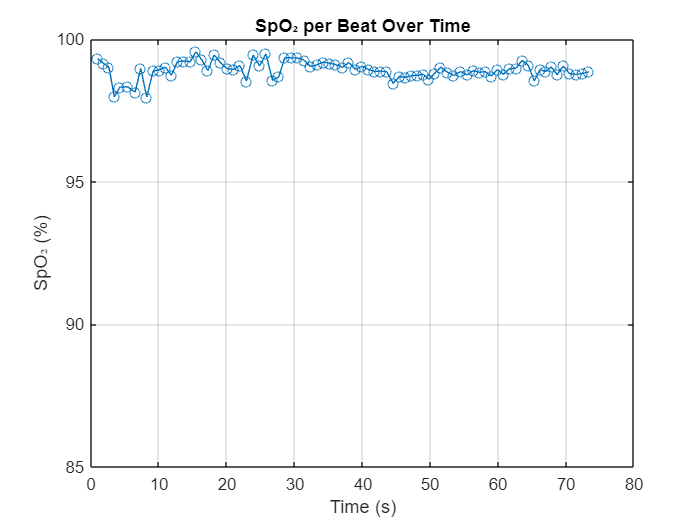

% Plot SpO₂ per beat over time
figure('Name', 'SpO₂ per Beat Over Time');
plot(beat_times, SpO2_per_beat, '-o');
title('SpO₂ per Beat Over Time');
xlabel('Time (s)'); ylabel('SpO₂ (%)');
ylim([85, 100]); % Adjust y-axis range as needed
grid on;

**Expected Outcome:**

- A plot of SpO₂ per beat over time, showing the variability in measurements. Typically in the range of 90% to 100% for healthy individuals

**Reflective Questions:**

- **Per-Beat Calculation:** How does calculating SpO₂ per beat affect the measurement's variability?

- **Data Quality:** Are there any beats where the SpO₂ value seems anomalous? What might cause this?

### **Step 9: Moving Average of SpO₂ per Beat**

SpO₂ measurements can be affected by noise and physiological variations. Calculating a moving average over multiple beats can provide a more stable estimate.

**Exercise 7:** Compute SpO₂ over moving windows of **1 beat**, **8 beats**, **16 beats**, and **the entire 30-second period**, and analyze the effect on measurement stability.

**Instructions:**

- Calculate SpO₂ over moving windows of the specified sizes

- Use the `movmean` function to compute moving averages

- Plot the SpO₂ over time for each window size to compare their stability

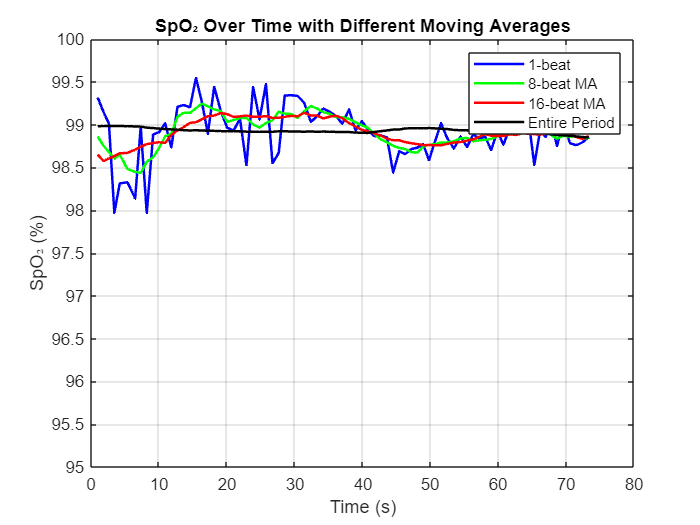

% --- Your code here ---
% Define window sizes in beats
window_sizes_beats = [1, 8, 16, num_beats];  % Including the entire period

% Initialize cell array to store SpO₂ moving averages
SpO2_moving_avg = cell(length(window_sizes_beats), 1);

for i = 1:length(window_sizes_beats)
    ws = window_sizes_beats(i);
    % Use moving average over SpO₂ per beat
    SpO2_moving_avg{i} = movmean();
end

% Plot SpO₂ over time for different window sizes
figure('Name', 'SpO₂ Over Time with Different Moving Averages');
colors = {'b', 'g', 'r', 'k'};  % Added 'k' (black) for the entire period
for i = 1:length(window_sizes_beats)
    plot(beat_times, SpO2_moving_avg{i}, 'Color', colors{i}, 'LineWidth', 1.5);
    hold on;
end
title('SpO₂ Over Time with Different Moving Averages');
xlabel('Time (s)'); ylabel('SpO₂ (%)');
legend('1-beat', '8-beat MA', '16-beat MA', 'Entire Period');
ylim([95, 100]);
grid on;

**Expected Observations:**

**1-beat Moving Average:**

- Shows the most variability, reflecting beat-to-beat fluctuations

**8-beat and 16-beat Moving Averages:**

- Provide increasingly smoother curves, reducing the effect of short-term variations.

**Entire Period Moving Average:**

- Represents a single average value across the entire dataset, appearing as a straight line.

**Reflective Questions:**

**Window Size Effect:**

- How does the inclusion of the entire period affect the interpretation of SpO₂ measurements?

- Does the moving average over the entire period provide meaningful information for real-time monitoring?

**Data Interpretation:**

- How do the different window sizes help in balancing between responsiveness and stability in SpO₂ measurements?

- In a clinical setting, which moving average window size might be most appropriate, and why?

### **Step 10: Comparing with Reference Measurements**

Comparing your computed SpO₂ and pulse rate values with those obtained from the reference device helps validate your measurements and assess the accuracy of your algorithms.

**Exercise 8:** Compare the computed values with the reference measurements and calculate the percentage errors.

**Instructions:**

- Use the average pulse rate and SpO₂ over the 30-second period

- Replace placeholder values with your actual reference measurements

- Calculate the percentage errors between the computed values and the reference measurements

- Discuss possible reasons for any discrepancies observed

% --- Your code here ---
% Average computed values
avg_pulse_rate = mean();
avg_SpO2 = mean()  % Using 8-beat moving average

avg_SpO2 = 98.9084


% Reference values (replace with actual measurements)
ref_pulse_rate = P1_Ref_PR;   % From your recorded data

ref_pulse_rate = 60

ref_SpO2 = P1_Ref_SpO2;       % From your recorded data

ref_SpO2 = 90


% Calculate percentage errors
pulse_rate_error = ((avg_pulse_rate - ref_pulse_rate) / ref_pulse_rate) * 100;
SpO2_error = ((avg_SpO2 - ref_SpO2) / ref_SpO2) * 100;

% Display errors
disp(['Pulse Rate Error: ', num2str(pulse_rate_error), '%']);

Pulse Rate Error: 9.8422%


disp(['SpO₂ Error: ', num2str(SpO2_error), '%']);

SpO₂ Error: 9.8982%


**Expected Outcome:**

- Percentage errors indicating how close your measurements are to the reference values

**Reflective Questions:**

- **Error Analysis:** Are the computed values within an acceptable range compared to the reference measurements?

- **Possible Discrepancies:** What factors might contribute to differences between your measurements and the reference device?

- **Algorithm Limitations:** How might your signal processing approach affect the accuracy of the results?

### **Step 11: Analyzing the Impact of Motion Artifacts**

Motion artifacts can significantly degrade the quality of PPG signals, leading to inaccurate measurements. It is important to understand how motion affects signal processing and to explore methods to mitigate its impact.

**Exercise 9:** Analyze the data from Periods 2 and 3 (with mild and severe finger motion) and observe the effects of motion artifacts on signal quality and measurement accuracy.

**Instructions:**

- Repeat Steps 1 to 10 for the data from Periods 2 and 3

- Compare the filtered signals, peak detection results, and computed SpO₂ and pulse rate values with those from Period 1

- Observe and document any differences in signal quality and measurement accuracy

**Reflective Questions:**

- **Signal Degradation:** How did motion artifacts affect the raw and filtered signals?

- **Measurement Accuracy:** Were you able to accurately extract pulse rate and SpO₂ during motion?

- **Mitigation Strategies:** What strategies could be employed to improve algorithm robustness under motion conditions?

### **Step 12: Investigating the Influence of Respiration Rate**

Changes in respiration rate can influence cardiovascular dynamics and affect PPG signals. Understanding this relationship can provide insights into physiological responses.

**Exercise 10:** Analyze the data from Period 5 (with varying respiration rates) to investigate the impact of respiration rate on SpO₂ and pulse rate measurements.

**Instructions:**

- Repeat the analysis steps for the data from Period 5.

- Observe any trends or changes in pulse rate and SpO₂ corresponding to different respiration rates.

- Plot pulse rate and SpO₂ over time alongside respiration rate to visualize any correlations.

**Reflective Questions:**

- **Physiological Impact:** Did pulse rate or SpO₂ levels change with different respiration rates?

- **Mechanisms:** What physiological mechanisms might explain any observed changes?

- **Clinical Relevance:** How could this information be useful in clinical settings?

## Conclusion

In this lab, you have applied signal processing techniques to real-world PPG data collected from red and IR sensors. By filtering the signals, separating AC and DC components, and implementing peak detection algorithms, you were able to extract pulse rate and compute SpO₂ levels. Comparing your results with reference measurements provided insights into the accuracy of your methods and the challenges posed by motion artifacts and physiological variations.

Understanding the principles of pulse oximetry and the importance of robust signal processing is crucial for developing reliable medical devices and algorithms. The ability to critically analyze and interpret physiological data is an essential skill in biomedical engineering and healthcare technology.

**Final Reflective Questions:**

- **Filter Parameters:** How did the choice of filter parameters impact the quality of the processed signals?

- **Processing Challenges:** What were the main challenges in processing the PPG signals, and how did you address them?

- **Algorithm Improvement:** How can signal processing algorithms be improved to handle motion artifacts more effectively?

- **Clinical Importance:** Why is it important to accurately measure SpO₂ and pulse rate in clinical settings?

### Note to Students

Understanding the code and the underlying concepts is crucial. While tools like ChatGPT and built-in MATLAB functions can assist with code generation, developing a deep comprehension of the material will enable you to apply these techniques effectively in practical situations and troubleshoot issues that automated tools cannot anticipate.

## End of Lab